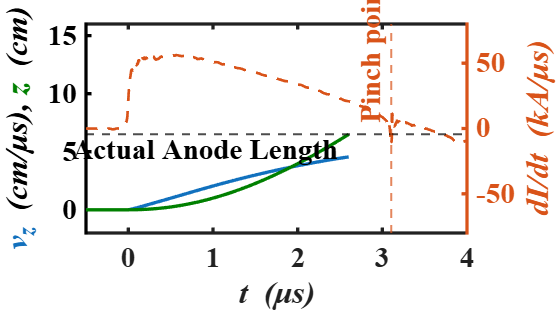

clear; clc; close all;

% =========================================================
% Data Acquisition
% =========================================================
if exist('Workspace2.mat', 'file')
    load('Workspace2.mat');
else
    t_mock = (0:0.01:5)';

    integrated_results = [ ...
        t_mock, ...
        (120 - t_mock*2).*ones(size(t_mock, 1), 19) ...
    ];

    warning('Workspace2.mat not found. Using simulated data.');
end

time = integrated_results(:, 1)*1E-6;
Ex = integrated_results(:, 2:20)*1000;

% =========================================================
% Physical Constants and Model Parameters
% =========================================================
mu0 = 4*pi*1E-7;

a = 0.0125;
b = 0.025;
L_anode = 0.065;

rho0 = 4.3E-3;
fm = 0.05;

t_start_search = 3.0E-6;
t_end_search = 3.5E-6;

n1 = 12;
n2 = 12;

n2 = min(n2, size(Ex, 2));
shot_range = n1:n2;

% =========================================================
% Snowplow Model Calculation
% =========================================================
num_all_shots = size(Ex, 2);
dt = time(2) - time(1);

K_axial = (mu0*log(b/a)) / ...
          (4*pi^2*(b^2 - a^2)*rho0*fm);

Results = struct();

for s = 1:num_all_shots

    I = Ex(:, s);
    dIdt = [diff(I)./dt; 0];

    % Identify the pinch point within the specified time window.
    search_indices = find( ...
        time >= t_start_search & time <= t_end_search ...
    );

    if isempty(search_indices)
        [~, pinch_idx] = min(dIdt);
    else
        [~, local_min_pos] = min(dIdt(search_indices));
        pinch_idx = search_indices(local_min_pos);
    end

    z = zeros(pinch_idx, 1);
    vz = zeros(pinch_idx, 1);

    Integral_I2 = 0;

    for k = 2:pinch_idx

        Integral_I2 = Integral_I2 + I(k)^2*dt;
        term_at_k = K_axial*Integral_I2;

        z(k) = sqrt(z(k-1)^2 + 2*term_at_k*dt);

        if z(k) > 0
            vz(k) = term_at_k/z(k);
        end
    end

    Results(s).t = time(1:pinch_idx);
    Results(s).I = I(1:pinch_idx);
    Results(s).vz = vz;
    Results(s).z = z;
    Results(s).pinch_time = time(pinch_idx);

end

% =========================================================
% Plot Configuration
% =========================================================
allFontSize = 22;

dataLineWidth = 2.5;
boxLineWidth = 2.5;

pinchColor = [0.85 0.325 0.098];
pinchLineWidth = 1.5;
pinchLineStyle = '--';

% Normalized annotation positions.
pinchLabelYPos = 0.85;
anodeLabelXPos = 0.30;

set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');
set(0, 'DefaultAxesFontWeight', 'bold');
set(0, 'DefaultTextFontWeight', 'bold');

fig = figure( ...
    'Color', 'w', ...
    'Units', 'normalized', ...
    'Position', [0.1 0.1 0.7 0.7] ...
);

hold on;

colors = lines(max(length(shot_range), 7));
posColor = [0.0 0.5 0.0];

% =========================================================
% Axial Phase Visualization
% =========================================================
for i = 1:length(shot_range)

    s = shot_range(i);

    % Limit the model curves to the anode length.
    cut_idx = find(Results(s).z >= L_anode, 1);

    if isempty(cut_idx)
        cut_idx = length(Results(s).z);
    end

    t_plot = Results(s).t(1:cut_idx)*1E6;
    vz_plot = Results(s).vz(1:cut_idx)/1E4;
    z_plot = Results(s).z(1:cut_idx)*100;

    % Left Y-axis: Axial velocity and position.
    yyaxis left;

    plot(t_plot, vz_plot, ...
        'Color', colors(i, :), ...
        'LineWidth', dataLineWidth);

    plot(t_plot, z_plot, '-', ...
        'Color', posColor, ...
        'LineWidth', dataLineWidth);

    c_vz = sprintf('%0.2f %0.2f %0.2f', ...
        colors(i, 1), colors(i, 2), colors(i, 3));

    c_z = sprintf('%0.2f %0.2f %0.2f', ...
        posColor(1), posColor(2), posColor(3));

    ylabel_str = [ ...
        '\bf\color[rgb]{' c_vz '}\itv_z ' ...
        '\bf\color{black} (cm/\mus), ' ...
        '\color[rgb]{' c_z '}\itz ' ...
        '\bf\color{black} (cm)' ...
    ];

    ylabel(ylabel_str, ...
        'Interpreter', 'tex', ...
        'FontSize', allFontSize, ...
        'FontWeight', 'bold');

    ax = gca;
    ax.YAxis(1).Color = 'k';

    ylim([-2 16]);

    % Right Y-axis: Current derivative.
    yyaxis right;

    dIdt_full = [diff(Ex(:, s)/1000)./(dt*1E6); 0];

    plot(time*1E6, dIdt_full, '--', ...
        'Color', pinchColor, ...
        'LineWidth', 2);

    ylh_right = ylabel( ...
        '\bf\itdI/dt \bf (kA/\mus)', ...
        'Interpreter', 'tex', ...
        'FontSize', allFontSize, ...
        'FontWeight', 'bold');

    ylh_right.Color = pinchColor;
    ax.YAxis(2).Color = pinchColor;

    ylim([-80 80]);

    % Pinch point annotation.
    px = Results(s).pinch_time*1E6;

    xline(px, ...
        'LineStyle', pinchLineStyle, ...
        'Color', pinchColor, ...
        'LineWidth', pinchLineWidth, ...
        'HandleVisibility', 'off');

    y_limits = ylim;

    text(px, ...
        y_limits(1) + diff(y_limits)*pinchLabelYPos, ...
        '\bf Pinch point', ...
        'Interpreter', 'tex', ...
        'FontSize', allFontSize, ...
        'Color', pinchColor, ...
        'Rotation', 90, ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom');

    % Anode length reference and annotation.
    yyaxis left;

    yline(L_anode*100, 'k--', ...
        'LineWidth', 1.5, ...
        'HandleVisibility', 'off');

    x_limits = [-0.5 4.0];

    text( ...
        x_limits(1) + diff(x_limits)*anodeLabelXPos, ...
        L_anode*100, ...
        '\bf Actual Anode Length', ...
        'Interpreter', 'tex', ...
        'FontSize', allFontSize, ...
        'Color', 'k', ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'top', ...
        'FontName', 'Times New Roman', ...
        'FontWeight', 'bold');

end

% =========================================================
% Final Axis Formatting
% =========================================================
xlabel('\bf\itt \bf (\mus)', ...
    'Interpreter', 'tex', ...
    'FontSize', allFontSize, ...
    'FontWeight', 'bold');

xlim([-0.5 4.0]);

set(gca, ...
    'FontSize', allFontSize, ...
    'LineWidth', boxLineWidth, ...
    'Box', 'on', ...
    'TickLabelInterpreter', 'tex', ...
    'FontWeight', 'bold');